% Build Color Matricies
desiredSize = [512 512];
black3DArray = fnBuildCDataFromConstantColor([0.0 0.0 0.0], desiredSize);

red3DArray = fnBuildCDataFromConstantColor([1.0 0.0 0.0], desiredSize);
green3DArray = fnBuildCDataFromConstantColor([0.0 1.0 0.0], desiredSize);
blue3DArray = fnBuildCDataFromConstantColor([0.0 0.0 1.0], desiredSize);

tempConjunctionMask = logical(final_data_explorer_obj.amalgamationMasks.AlphaConjunctionMask);

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
    temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.Edge(i,:,:));
    temp.curr_edge_mask = temp.curr_edge_mask + squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:));
    
    
    im = image('CData', temp.curr_edge_mask, 'AlphaData', temp.curr_edge_mask);
%     im.AlphaData = 0.5;
end


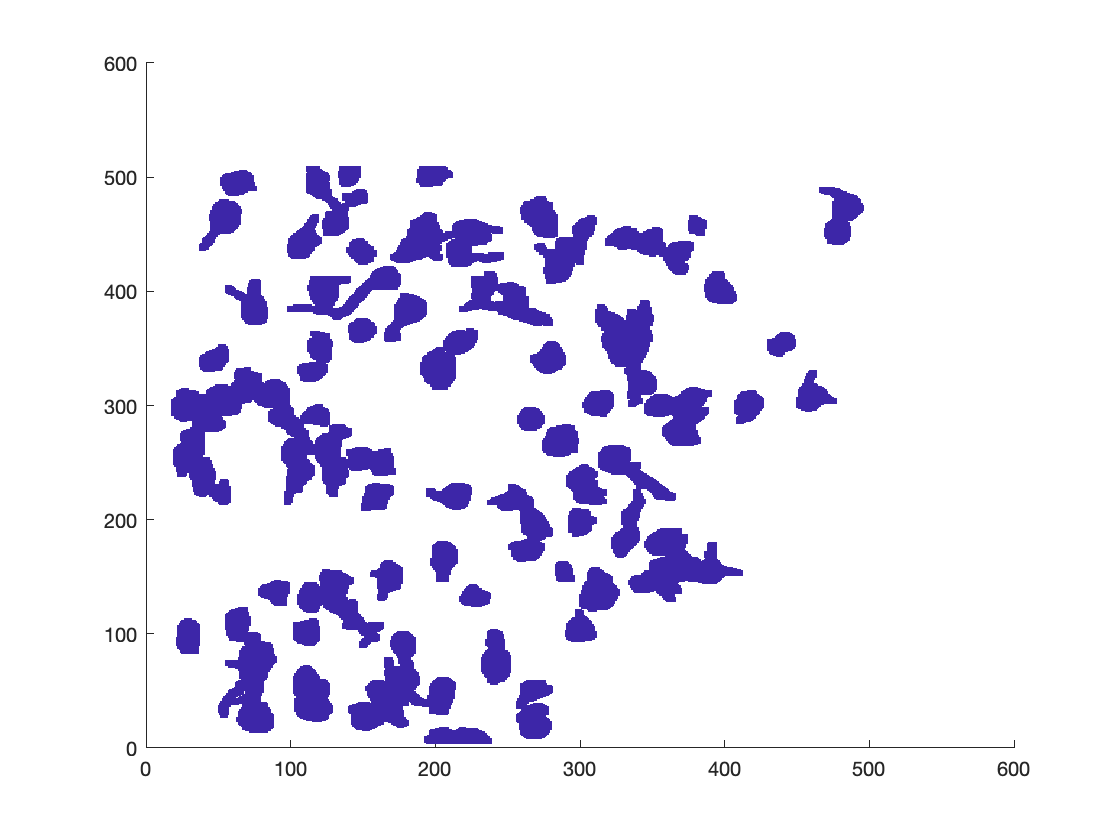

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
%     temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
    temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge1(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
    
    im = image('CData', temp.curr_edge_mask, 'AlphaData', temp.curr_edge_mask);
%     im.AlphaData = 0.5;
end

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
    temp.curr_revised_OutsetEdge0 = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:)) - squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:));
    
    
    im = image('CData', red3DArray, 'AlphaData', temp.curr_revised_OutsetEdge0);
    
    temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.Edge(i,:,:));
    im2 = image('CData', black3DArray, 'AlphaData', temp.curr_edge_mask);

end


function result3DArray = fnBuildCDataFromConstantColor(colorToRepeat, desiredSize)

%     result3DArray = zeros([3, desiredSize(1), desiredSize(2)]);
%     for i = 1:3
%         result3DArray(i,:,:) = ones(desiredSize) .* colorToRepeat(i);
%     end 

    result3DArray = zeros([desiredSize(1), desiredSize(2), 3]);

    % compRed = ones(desiredSize) .* colorToRepeat(1);
    % compGreen = ones(desiredSize) .* colorToRepeat(2);
    % compBlue = ones(desiredSize) .* colorToRepeat(3);
    % Loop through the 3 color components (R G B):
    for i = 1:desiredSize(1)
        for j = 1:desiredSize(2)
            result3DArray(i,j,:) = colorToRepeat;
        end
    end 

return 

end